syms rho
syms kappa_o l_o
syms l_A
syms l_B

assume([rho ...
    kappa_o l_o ...
    l_A ...
    l_B], 'real')

syms x y
assume([x y], 'real')

struct_vals = struct();
struct_vals.rho = 0.03; % Meters
struct_vals.l_A = 0.12; % Meters
struct_vals.l_B = 0.13; % Meters

struct_xy = struct();
struct_xy.l_o = x;
struct_xy.kappa_o = y;

## Construct cost function

Given an arbitrary base curve flow-vector of $\tilde{h}_o^* = [l_o^*\ 0\ l_o^* \kappa_o^*]^T$, we can find the corresponding individual flow-vectors of a muscle $x$: $\tilde{h}_x^* = {}_A Ad_o \tilde{h}_o^* =  [l_x^*\ 0\ l_x^* \kappa_x^*]^T$. If we multiply this $\tilde{h}_x^*$ by $[1\ 0\ 0]$, we can calculate the length that muscle $x$ needs to satisfy the geometric constraints, given the hypothetical base curve $\tilde{h}_o^*$. Our entire question can then be posed as such: **What base curve **$\tilde{h}_o$** will minimize the difference between the actual muscle lengths given the current pressures, and the muscle lengths needed to satisfy the constraints?**

Using the aforementioned simplifications, we can reformulate the distance-error of a single muscle $x$ as such:


$$U_x = ([1\ 0\ 0] \cdot {}_xAd_o \cdot \tilde{h}_o - l_x)^2$$


To minimize the errors of both muscles, then we need to combine the errors of each muscles.


$$U_{all} = ([1\ 0\ 0] \cdot {}_AAd_o \cdot \tilde{h}_o - l_A)^2 + ([1\ 0\ 0] \cdot {}_BAd_o \cdot \tilde{h}_o - l_B)^2$$


Now that we have formulated the equations, we can give them to an unconstrained optimization solver such as `fminsearch()`

ad_o_A = ad_se2(0, [0, rho/2]);
ad_o_B = ad_se2(0, [0, -rho/2]);

ad_A_o = inv(ad_o_A);
ad_B_o = inv(ad_o_B);

cost = ([1 0 0]*ad_A_o*l_o*[1; 0; kappa_o] - l_A)^2 + ...
        ([1 0 0]*ad_B_o*l_o*[1; 0; kappa_o] - l_B)^2;

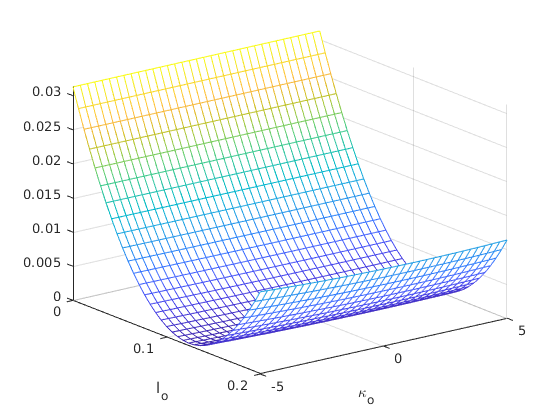

bounds = [0, 0.2, -5, 5]; %[l_o min, l_o max, k_o min, k_o max]

figure()
fmesh(chain_subs(cost, {struct_vals, struct_xy}), bounds)
xlabel("l_o")
ylabel("\kappa_o")

view([52.8000 23.4000])

Here we can see the error given different $l_o$ and $\kappa_o$ values.

% Convert symbolic cost function to function handle usable for fminsearch
cost_func = matlabFunction(chain_subs(cost, {struct_vals, struct_xy})); 
f_cost = @(x) cost_func(x(1), x(2));

% Fminsearch!
q_o_optim = fminsearch(f_cost, [0, 0])

q_o_optim =     0.1250    2.6667


h_o_tilde_optim = q_o_optim(1) * [1; 0; q_o_optim(2)] % reconstruct flow-vector from configuration variables

h_o_tilde_optim =     0.1250
         0
    0.3333


% Using the base curve, we cahn then recompute the flow-vectors of the
% individual muscles

% Here I just extracted the curvatures for easier comparison to the other
% examples
kappa_A = [0 0 1] * eval(subs(ad_A_o * h_o_tilde_optim / l_A, struct_vals))

kappa_A = 2.7778

kappa_B = [0 0 1] * eval(subs(ad_B_o * h_o_tilde_optim / l_B, struct_vals))

kappa_B = 2.5641

v_A = ad_A_o' * [1; 0; 0];
v_B = ad_B_o' * [1; 0; 0];
mat_M = v_A*v_A' + v_B*v_B';

eval(subs(mat_M * h_o_tilde_optim, struct_vals))

ans =     0.2500
         0
    0.0002


b = l_A * v_A + l_B * v_B;
eval(subs(b, struct_vals))

ans =     0.2500
         0
    0.0001


## Calculate Analytic Base Curve via Least Squares

Since given our linear-material assumption, our cost function is a quadrtic (a norm), an analytic solution for its minimum exists as solving a least-squares problem.

%TODO: Walk through the algebra for how we got to $\mathbf{M}\tilde{h}_o = b$ from the quadratic cost function.

$\mathbf{M} \tilde{h_o} = b$, so $\tilde{h_o} = \mathbf{M}^+ b$. Here we use `pinv()` to calculate the pseudoinverse. A couple notes with the pseudoinverse:

- M is square but singular ( `rank(M) = 2,` so we can't just use $\mathbf{M}^+ = (\mathbf{M}^{T}\mathbf{M})^{-1} \mathbf{M}^T$. Instead we need to use the SVD pseudoinverse

- The singularity of M stems from the fact that since we assume 0 shearing in the muscles, we therefore assume the arclength of a muscle is just the length along its body x axis, which is what we check in the cost function. Thus, we are not constraining the 2nd element of $\tilde{h_o}$, which allows the shear to be any value. Therefore, `null(M) = [0; 1; 0]`. By using the pseudoinverse, we attain the minimal-norm / least-value $\tilde{h_o}$, which contains a shear value of 0.

% Calculate analytic h_o_tilde
h_o_tilde_analytic = eval(subs(pinv(mat_M) * b, struct_vals))

h_o_tilde_analytic =     0.1250
         0
    0.3333


% Exctract values
l_o_analytic = h_o_tilde_analytic(1);
kappa_o_analytic = h_o_tilde_analytic(3) / l_o_analytic;

% Analytic configuration vector
q_o_analytic = [l_o_analytic, kappa_o_analytic]

q_o_analytic =     0.1250    2.6667
